Task A.

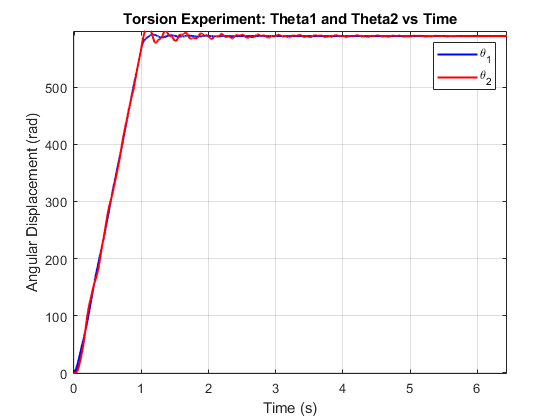

clear all

%% Load experimental data
% Assuming data is stored in 'data.csv' with columns: Time, Theta1, Theta2
data = load('Torsion_data_A.mat');
time = data.Torsion_Data.time(:,1);
theta1 = data.Torsion_Data.signals(4).values;
theta2 = data.Torsion_Data.signals(3).values;

%% Load experimental data
data = load('Torsion_data_A.mat');
%time = data.Torsion_Data.time(501:1001,1);
% theta1 = data.Torsion_Data.signals(4).values(501:1001);
% theta2 = data.Torsion_Data.signals(3).values(501:1001);

%% Plot the data
figure;
plot(time, theta1, 'b', 'LineWidth', 1.5); hold on;
plot(time, theta2, 'r', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Angular Displacement (rad)');
title('Torsion Experiment: Theta1 and Theta2 vs Time');
legend('\theta_1', '\theta_2');
xlim([min(time) max(time)]);


%% Find Peaks in Oscillation (For Theta1)
locs = [1.17;1.416;1.704;1.982];
pks = [591.8;590.5;590;589.7]./(2*pi);

% Select first and nth peaks for damping ratio calculation
O1 = pks(1)-589.39./(2*pi);  % First peak
On = pks(end)-589.39./(2*pi); % nth peak
n = length(pks); % Number of peaks

% Compute time period of oscillation
Tosc = (locs(end) - locs(1)) / (n - 1);  % Equation (2.15)

% Compute damped natural frequency
omega_d = 2 * pi / Tosc;  % Equation (2.16)

% Compute damping ratio (logarithmic decrement method)
delta = log(O1 / On) / (n-1);
zeta1 = 1 / sqrt(1 + (4 * pi^2)/delta^2);  % Equation (2.19)

% Compute undamped natural frequency
omega_n = omega_d / sqrt(1 - zeta1^2);  % Equation (2.17)

%% Estimate Stiffness Ks1
J1 = 0.0022;  % Example value, update based on your system inertia
K_s1 = J1 * omega_n^2;  % Equation (2.13)

%% Find Peaks in Oscillation (For Theta2)
locs2 = [1.116;1.358;1.66;1.888];
pks2 = [599.8;599.4;595.1;594]./(2*pi);

%% Repeat for Theta2
O1_2 = pks2(1)-589.22./(2*pi);
On_2 = pks2(end)-589.22./(2*pi);
n2 = length(pks2);

Tosc2 = (locs2(end) - locs2(1)) / (n2 - 1);
omega_d2 = 2 * pi / Tosc2;
delta2 = log(O1_2 / On_2) / (n2 - 1);
zeta2 = 1 / sqrt(1 + (4 * pi^2)/delta2^2);
omega_n2 = omega_d2 / sqrt(1 - zeta2^2);

% Estimate Stiffness Ks2
J2 = 0.000545;
K_s2 = J2 * omega_n2^2;

%% Display Results
fprintf('Damped Natural Frequency (Theta1): %f rad/s\n', omega_d);

Damped Natural Frequency (Theta1): 23.213739 rad/s


fprintf('Undamped Natural Frequency (Theta1): %f rad/s\n', omega_n);

Undamped Natural Frequency (Theta1): 23.350727 rad/s


fprintf('Damping Ratio (Theta1): %f\n', zeta1);

Damping Ratio (Theta1): 0.108161


fprintf('Estimated Stiffness K_s1: %f Nm/rad\n', K_s1);

Estimated Stiffness K_s1: 1.199564 Nm/rad



fprintf('\nDamped Natural Frequency (Theta2): %f rad/s\n', omega_d2);


Damped Natural Frequency (Theta2): 24.416523 rad/s


fprintf('Undamped Natural Frequency (Theta2): %f rad/s\n', omega_n2);

Undamped Natural Frequency (Theta2): 24.438204 rad/s


fprintf('Damping Ratio (Theta2): %f\n', zeta2);

Damping Ratio (Theta2): 0.042113


fprintf('Estimated Stiffness K_s2: %f Nm/rad\n', K_s2);

Estimated Stiffness K_s2: 0.325488 Nm/rad


Task B:

%% Compute Viscous Damping Coefficients
B1 = 2 * zeta1* omega_n * J1

B1 = 0.0111

B2 = 2 * zeta2 * omega_n2 * J2

B2 = 0.0011

Task C:

Task D: